%filename: sa.m
clear all % clear all variables
close all % and figures
clc       % and Command Window
global T TS TMAX QMAX;
global Rs Csa dt;
in_sa %initialization

   
    for klok=1:klokmax 
      
      t=klok*dt;
      QAo=QAo_now(t);
      Psa=Psa_new(Psa,QAo); %new Psa overwrites old
      %Store values in arrays for future plotting:
      t_plot(klok)=t;
      QAo_plot(klok)=QAo;
      Psa_plot(klok)=Psa;
    end


%Calculate and print cardiac output
%Cardiac output = average flow over one cardiac cycle
%Use the last few cycles to get steady-state value
cycles_to_use = 4; % Use last 4 cycles
cycle_length = round(T/dt); % Number of time steps per cycle
start_idx = klokmax - cycles_to_use * cycle_length + 1;
cardiac_output = mean(QAo_plot(start_idx:end));
fprintf('Cardiac Output: %.2f L/min\n', cardiac_output);

Cardiac Output: 5.60 L/min



%Calculate and print systolic and diastolic pressures
%Use the last few cycles to get steady-state values
pressure_data = Psa_plot(start_idx:end);
systolic_pressure = max(pressure_data);
diastolic_pressure = min(pressure_data);
fprintf('Systolic Pressure: %.1f mmHg\n', systolic_pressure);

Systolic Pressure: 114.8 mmHg


fprintf('Diastolic Pressure: %.1f mmHg\n', diastolic_pressure);

Diastolic Pressure: 85.2 mmHg


fprintf('Current Compliance (Csa): %.4f L/mmHg\n', Csa);

Current Compliance (Csa): 0.0015 L/mmHg


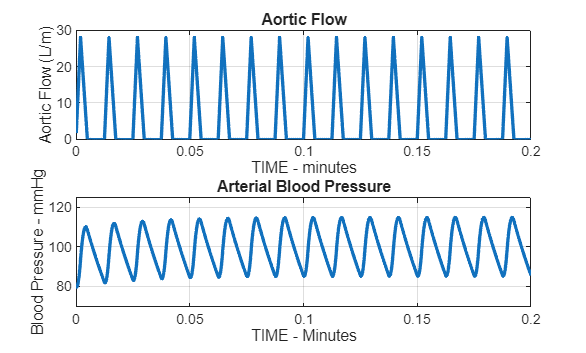


%Now plot results in one figure 
%with QAo(t) in upper frame
% and Psa(t) in lower frame
figure('color','white')
subplot(2,1,1), plot(t_plot,QAo_plot,'linewidth',2)
xlabel('TIME - minutes')
ylabel('Aortic Flow (L/m)')
title('Aortic Flow')
grid on;
subplot(2,1,2), plot(t_plot,Psa_plot,'linewidth',2)
xlabel('TIME - Minutes')
ylabel('Blood Pressure - mmHg')
TITLE=['Arterial Blood Pressure'];
title(TITLE)
grid on,
axis([0, max(t_plot), min(Psa_plot)-10, max(Psa_plot)+10]);